clear;clc;close('all');

%%parameter settings
t0=0;
dt=0.0001;
tn=1;
x0=-0.25;
dx=0.005;
xn=0.25;
y0=-0.25;
dy=0.005;
yn=0.25;

h=0.525*10^-3;
rho=2330;
E=130*10^9;
Pratio=0.28;
D=E*h^3/(12*(1-Pratio^2))

D = 1.7010


c=3.05;
r=(c*dt/dx)^2;

A=0.0015

A = 0.0015

g=9.8;
b=5.55;
COR=0.5;

%%create grid
t=(t0:dt:tn);
x=(x0:dx:xn);
y=(y0:dy:yn);
global u
u=zeros(length(x),length(y),length(t));

source_pos_x=fix(length(x)/2)+1;
source_pos_y=fix(length(y)/2)+1;

% set_BCIC(t,x,y,r,source_pos_x,source_pos_y);
% iterate(t,x,y,r,source_pos_x,source_pos_y);

mode=[4,2];

%disp("w for membrane");
%w=c*sqrt(((mode(1)-1)*pi/(x(end)-x(1)))^2+((mode(2)-1)*pi/(y(end)-y(1)))^2)

disp("w for free bound plate");

w for free bound plate


alpha=fzero(@(x)tan(x)+tanh(x),[0.1+pi/2+(mode(1)-2)*pi -0.1+pi/2+(mode(1)-1)*pi]);
beta=fzero(@(x)tan(x)+tanh(x),[0.1+pi/2+(mode(2)-2)*pi -0.1+pi/2+(mode(2)-1)*pi]);

% alpha=fzero(@(x)tanh(x)-tan(x),[0.1+pi/2+(mode(1)-2)*pi -0.1+pi/2+(mode(1)-1)*pi]);
% beta=fzero(@(x)tanh(x)-tan(x),[0.1+pi/2+(mode(2)-2)*pi -0.1+pi/2+(mode(2)-1)*pi]);

w=((alpha/(x(end)-x(1)))^2+(beta/(y(end)-y(1)))^2)*sqrt(D/(rho*h))

w = 378.4425

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
pnx=11;
pny=11;
pn=pnx*pny

pn = 121

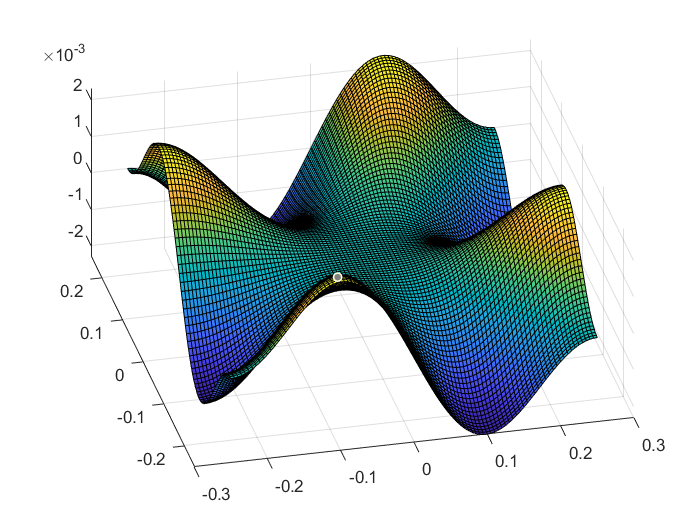

global rp   %[x,y,z] position  z is height
global vp
global rp0
global vp0

rp=zeros(pn,3,length(t));
vp=zeros(pn,3,length(t));

rp0=zeros(pn,3);
vp0=zeros(pn,3);

%rp0=[-0.2,0,0.006;-0.15,0,0.006;-0.1,0,0.006;-0.05,0,0.006;0.05,0,0.006;0.1,0,0.006;0.15,0,0.006;0.2,0,0.006];
rp0x=linspace(x(1),x(end),pnx+2);
rp0y=linspace(y(1),y(end),pny+2);
for px=1:1:pnx
    for py=1:1:pny
        rp0(py+(px-1)*pny,1)=rp0x(px+1);
        rp0(py+(px-1)*pny,2)=rp0y(py+1);
    end
end

%vp0=[0,0,0;0,0,0;0,0,0;0,0,0;0,0,0;0,0,0;0,0,0;0,0,0];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

uA=zeros(length(x),length(y),1);
ew=0;
%[uA,ew]=eigenmode(A,c,mode,x,dx,y,dy,t,0,uA,ew);
uA=analytic_standing_wave(mode,A,w,x,y,t,0,uA);

u_plot(x,y,uA);

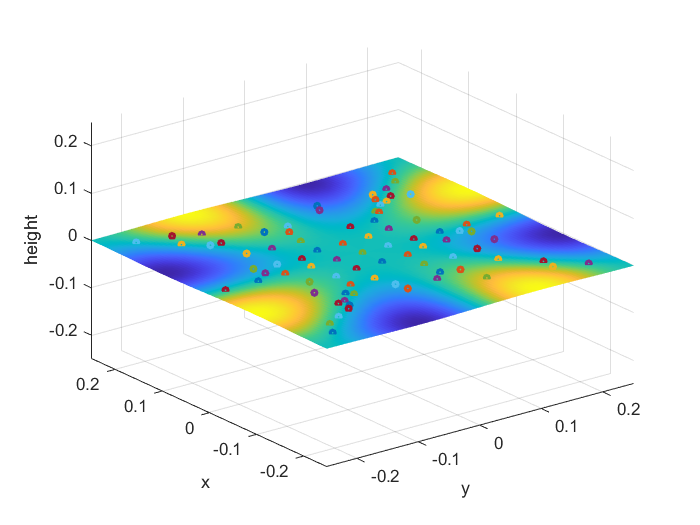


Tt=50;
gap=10000;
global trajectory
trajectory=zeros(pn,2,(length(t)-1)/gap*Tt+1);

global value
value=zeros(1,(length(t)-1)/gap*Tt+1);

for I=0:1:Tt-1
    motion(pn,g,b,COR,A,x,dx,y,dy,t,dt,I);
    %eigenmode(A,c,mode,x,dx,y,dy,t,I,uA,ew);
    analytic_standing_wave(mode,A,w,x,y,t,I+1,uA);
    %animate(pn,x,y,t);
    for ii=1:1:(length(t)-1)/gap
        trajectory(:,1,(length(t)-1)/gap*I+ii)=rp(:,1,gap*(ii-1)+1);
        trajectory(:,2,(length(t)-1)/gap*I+ii)=rp(:,2,gap*(ii-1)+1);
        value((length(t)-1)/gap*I+ii)=moranI(pn,1+fix((rp(:,1,gap*(ii-1)+1)-x(1))/dx),1+fix((rp(:,2,gap*(ii-1)+1)-y(1))/dy),x,y);
    end
end
trajectory(:,1,(length(t)-1)/gap*Tt+1)=rp(:,1,end);
trajectory(:,2,(length(t)-1)/gap*Tt+1)=rp(:,2,end);
value((length(t)-1)/gap*Tt+1)=moranI(pn,1+fix((rp(:,1,end)-x(1))/dx),1+fix((rp(:,2,end)-y(1))/dy),x,y);
animate(pn,x,y,t);

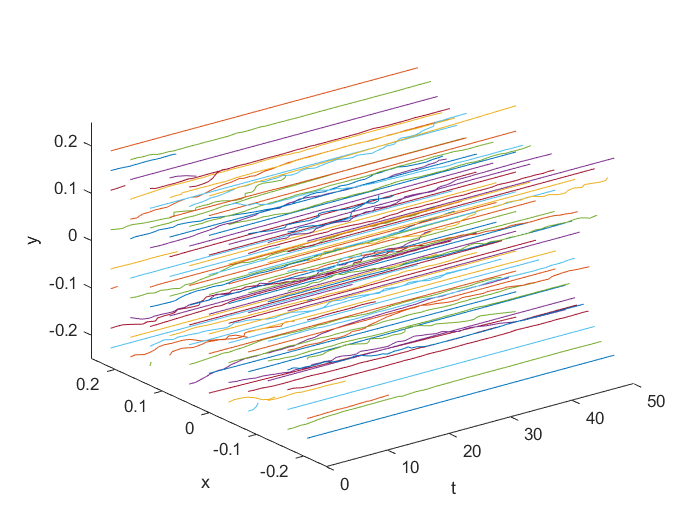


tr_time_coordinate=0:gap/(length(t)-1):t(end)*Tt;
tr_plot(pn,tr_time_coordinate);

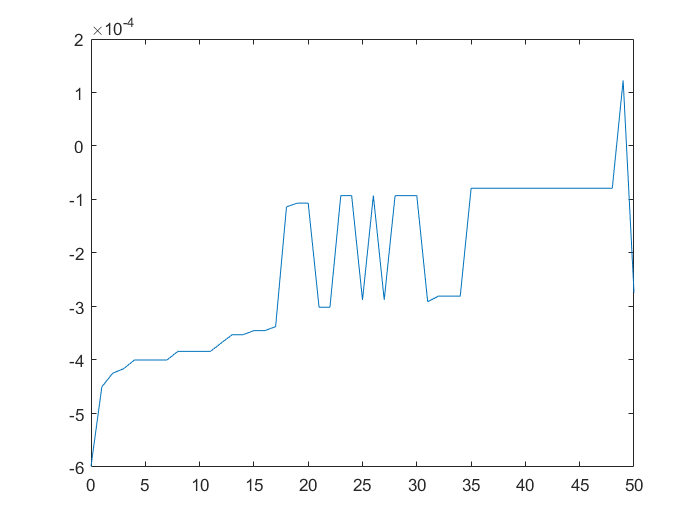

value_plot(tr_time_coordinate);

function set_BCIC(t,x,y,r,source_pos_x,source_pos_y)
    global u
    %%Initial condition
    %u(i,j,1)=0
    
    %%Boundary condition
    %u(1,j,k)=u(length(x),j,k)=u(i,1,k)=u(i,length(y),k)=0
end

function f=source_vibration(t)
    w=15*2*pi;
    f=1*sin(w*t);
end

function iterate(t,x,y,r,source_pos_x,source_pos_y)
    global u
    
    sp=0;
    for k=2:1:length(t)-1
        for j=2:1:length(y)-1
            for i=2:1:length(x)-1
                u(i,j,k+1)=2*u(i,j,k)-u(i,j,k-1)+r*(u(i+1,j,k)+u(i-1,j,k)+u(i,j+1,k)+u(i,j-1,k)-4*u(i,j,k));
                u(source_pos_x,source_pos_y,k+1)=source_vibration(t(k+1));
                
                if(u(i,j,k+1)>100)
                    EX=[i,j,k+1];
                    disp(EX);
                    sp=1;
                    break;
                end
            end
            %free edge
            u(1,j,k+1)=u(2,j,k+1);
            u(length(x),j,k+1)=u(length(x)-1,j,k+1);
        end
        %free edge
        for i=2:1:length(x)-1
            u(i,1,k+1)=u(i,2,k+1);
            u(i,length(y),k+1)=u(i,length(y)-1,k+1);
        end
        
        
        if(sp)
            break;
        end
    end
    
    %%try plot
    figure
    k=surf(t,y,squeeze(u(source_pos_x,:,:)));
    xlabel("time");
    ylabel("y")
    zlabel("height")
    set(k,'LineStyle','none')
    
end

function [uA,ew]=eigenmode(A,c,mode,x,dx,y,dy,t,I,uA,ew)
    global u;
    
    if all(uA==0)
        %Dirichlet's boundary
%         FDMx=1/(dx^2)*(diag(-2+zeros(1,length(x)-2))+diag(1+zeros(1,length(x)-3),1)+diag(1+zeros(1,length(x)-3),-1));
%         [Vx,Dx]=eig(FDMx);
%         FDMy=1/(dy^2)*(diag(-2+zeros(1,length(y)-2))+diag(1+zeros(1,length(y)-3),1)+diag(1+zeros(1,length(y)-3),-1));
%         [Vy,Dy]=eig(FDMy);
%         u(2:length(x)-1,2:length(y)-1,1)=Vx(:,length(x)-1-mode)*Vy(:,length(y)-1-mode)';

        %Neumann's boundary
        FDMx=(diag(-2+zeros(1,length(x)-2))+diag(1+zeros(1,length(x)-3),1)+diag(1+zeros(1,length(x)-3),-1));
        FDMx(1,1)=FDMx(1,1)+1;
        FDMx(length(x)-2,length(x)-2)=FDMx(length(x)-2,length(x)-2)+1;
        FDMx=1/(dx^2)*FDMx;
        [Vx,Dx]=eig(FDMx);
        FDMy=(diag(-2+zeros(1,length(y)-2))+diag(1+zeros(1,length(y)-3),1)+diag(1+zeros(1,length(y)-3),-1));
        FDMy(1,1)=FDMy(1,1)+1;
        FDMy(length(y)-2,length(y)-2)=FDMy(length(y)-2,length(y)-2)+1;
        FDMy=1/(dy^2)*FDMy;
        [Vy,Dy]=eig(FDMy);
        
        u(2:length(x)-1,2:length(y)-1,1)=Vx(:,length(x)-1-mode(1))*Vy(:,length(y)-1-mode(2))';
        u(2:length(x)-1,1,1)=u(2:length(x)-1,2,1);
        u(2:length(x)-1,length(y),1)=u(2:length(x)-1,length(y)-1,1);
        u(1,1:length(y),1)=u(2,1:length(y),1);
        u(length(x),1:length(y),1)=u(length(x)-1,1:length(y),1);
    
        %Mixed Dirichlet-Neumann boundary conditions boundary

        ew=c*sqrt(-Dx(length(x)-1-mode(1),length(x)-1-mode(1))-Dy(length(y)-1-mode(2),length(y)-1-mode(2)));
        uA=50*A*u(:,:,1);
    end
    
    for i=1:1:length(t)
        u(:,:,i)=uA*sin(ew*(t(end)*I+t(i)));
    end
    
end

function uA=analytic_standing_wave(mode,A,w,x,y,t,I,uA)
    global u
    if all(uA==0)
        for i=1:1:length(x)
            for j=1:1:length(y)
                %Membrane
                %u(i,j,1)=A*cos((mode(1)-1)*pi*(x(i)-x(1))/(x(end)-x(1)))*cos((mode(2)-1)*pi*(y(j)-y(1))/(y(end)-y(1)));
                %ColwellMethod
                u(i,j,1)=A*(cos((mode(1)-1)*pi*(x(i)-x(1))/(x(end)-x(1)))*cos((mode(2)-1)*pi*(y(j)-y(1))/(y(end)-y(1)))-cos((mode(2)-1)*pi*(x(i)-x(1))/(x(end)-x(1)))*cos((mode(1)-1)*pi*(y(j)-y(1))/(y(end)-y(1))));
                
                %Ritz
                if mod(mode(1)-1,2)==0
                    alpha=fzero(@(x)tanh(x)+tan(x),[0.1+pi/2+(mode(1)-2)*pi -0.1+pi/2+(mode(1)-1)*pi]);
                else
                    alpha=fzero(@(x)tanh(x)-tan(x),[0.1+pi/2+(mode(1)-2)*pi -0.1+pi/2+(mode(1)-1)*pi]);
                end
                alpha=fzero(@(x)tanh(x)+tan(x),[0.1+pi/2+(mode(1)-2)*pi -0.1+pi/2+(mode(1)-1)*pi]);
                beta=fzero(@(x)tanh(x)+tan(x),[0.1+pi/2+(mode(2)-2)*pi -0.1+pi/2+(mode(2)-1)*pi]);
                
                %SymPlate
%                 alpha=fzero(@(x)tanh(x)+tan(x),[0.1+pi/2+(mode(1)-2)*pi -0.1+pi/2+(mode(1)-1)*pi]);
%                 beta=fzero(@(x)tanh(x)+tan(x),[0.1+pi/2+(mode(2)-2)*pi -0.1+pi/2+(mode(2)-1)*pi]);
%                 u(i,j,1)=A*(cos(alpha*(x(i)-x(1))/(x(end)-x(1)))*cos(beta*(y(j)-y(1))/(y(end)-y(1)))-sin(alpha)*sin(beta)/sinh(alpha)/sinh(beta)*cosh(alpha*(x(i)-x(1))/(x(end)-x(1)))*cosh(beta*(y(j)-y(1))/(y(end)-y(1))));
                %AntisymPlate
%                 alpha=fzero(@(x)tanh(x)-tan(x),[0.1+pi/2+(mode(1)-2)*pi -0.1+pi/2+(mode(1)-1)*pi]);
%                 beta=fzero(@(x)tanh(x)-tan(x),[0.1+pi/2+(mode(2)-2)*pi -0.1+pi/2+(mode(2)-1)*pi]);
%                 u(i,j,1)=A*(sin(alpha*(x(i)-x(1))/(x(end)-x(1)))*sin(beta*(y(j)-y(1))/(y(end)-y(1)))-cos(alpha)*cos(beta)/cosh(alpha)/cosh(beta)*sinh(alpha*(x(i)-x(1))/(x(end)-x(1)))*sinh(beta*(y(j)-y(1))/(y(end)-y(1))));
            end
        end
        uA=u(:,:,1);
    end
    
    for k=1:1:length(t)
        u(:,:,k)=uA*sin(w*(t(end)*I+t(k)));
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function motion(pn,g,b,COR,A,x,dx,y,dy,t,dt,I)
    global rp
    global vp
    global u
    global rp0
    global vp0
	
    rp(:,:,1)=rp0;
    vp(:,:,1)=vp0;
    
    for k=2:1:length(t) 
        pos_register=rp(:,:,k-1);
		rp(:,:,k)=vp(:,:,k-1)*dt+rp(:,:,k-1); 
		vp(:,1,k)=vp(:,1,k-1)-b*vp(:,1,k-1)*dt;
		vp(:,2,k)=vp(:,2,k-1)-b*vp(:,2,k-1)*dt;
        vp(:,3,k)=vp(:,3,k-1)-b*vp(:,3,k-1)*dt-g*dt;
		
        for p=1:1:pn
            if rp(p,1,k)>=x(1) && rp(p,2,k)>=y(1) && rp(p,1,k)<=x(end) && rp(p,2,k)<=y(end) && rp(p,3,k)>=-A
                
                if 0.25*u(1+fix((rp(p,1,k)-x(1))/dx),1+fix((rp(p,2,k)-y(1))/dy),k)+0.25*u(2+fix((rp(p,1,k)-x(1))/dx),2+fix((rp(p,2,k)-y(1))/dy),k)+0.25*u(1+fix((rp(p,1,k)-x(1))/dx),2+fix((rp(p,2,k)-y(1))/dy),k)+0.25*u(2+fix((rp(p,1,k)-x(1))/dx),1+fix((rp(p,2,k)-y(1))/dy),k)>=rp(p,3,k)
                    
                    x1=x(1+fix((rp(p,1,k-1)-x(1))/dx));
                    x2=x(2+fix((rp(p,1,k-1)-x(1))/dx));
                    y1=y(1+fix((rp(p,2,k-1)-y(1))/dy));
                    y2=y(2+fix((rp(p,2,k-1)-y(1))/dy));
                    
                    z11=u(1+fix((rp(p,1,k-1)-x(1))/dx),1+fix((rp(p,2,k-1)-y(1))/dy),k-1);
                    z22=u(2+fix((rp(p,1,k-1)-x(1))/dx),2+fix((rp(p,2,k-1)-y(1))/dy),k-1);
                    z21=u(2+fix((rp(p,1,k-1)-x(1))/dx),1+fix((rp(p,2,k-1)-y(1))/dy),k-1);
                    z12=u(1+fix((rp(p,1,k-1)-x(1))/dx),2+fix((rp(p,2,k-1)-y(1))/dy),k-1);               
                    ut11=(u(1+fix((rp(p,1,k-1)-x(1))/dx),1+fix((rp(p,2,k-1)-y(1))/dy),k)-z11)/dt;
                    ut22=(u(2+fix((rp(p,1,k-1)-x(1))/dx),2+fix((rp(p,2,k-1)-y(1))/dy),k)-z22)/dt;
                    ut21=(u(2+fix((rp(p,1,k-1)-x(1))/dx),1+fix((rp(p,2,k-1)-y(1))/dy),k)-z21)/dt;
                    ut12=(u(1+fix((rp(p,1,k-1)-x(1))/dx),2+fix((rp(p,2,k-1)-y(1))/dy),k)-z12)/dt;
                    
                    ut=[0 0 0.25*ut11+0.25*ut22+0.25*ut21+0.25*ut12];
                    %assume 4 points are on the same plain
                    %the vertical unit vector of the plain
                    %[x1 y1 z11],[x2 y2 z22],[x1 y2 z12]
                    norm=cross([x2-x1 y2-y1 z22-z11],[x1-x1 y2-y1 z21-z12]);
                    norm=norm/sqrt(norm(1)^2+norm(2)^2+norm(3)^2);
                    
                    %vp(p,:,k)=2*dot(ut,n)*n-vp(p,:,k);
                    vp(p,:,k)=COR*(vp(p,:,k)-ut-2*dot(vp(p,:,k)-ut,norm)*norm)+ut;
                    rp(p,:,k)=vp(p,:,k)*dt+pos_register(p,:);
                    
                end
            else
                rp(p,:,k)=NaN;
                vp(p,:,k)=NaN;
            end
        end
    end
    rp0=rp(:,:,length(t));
    vp0=vp(:,:,length(t));
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function u_plot(x,y,uA)
    figure
    surf(y,x,uA);
end
function animate(pn,x,y,t)
global u
global rp
figure
for k = 1:100:length(t)
    S=surf(y,x,u(:,:,k));
    hold on;
    set(S,'LineStyle','none');
    for p=1:1:pn
        plot3(rp(p,2,k),rp(p,1,k),rp(p,3,k),"o","linewidth",2,'MarkerSize',3);
    end
    
    xlim([x(1) x(end)])
    ylim([y(1) y(end)])
    zlim([-0.25 0.25])
    xlabel("y");
    ylabel("x");
    zlabel("height")
    
    pause(0.0000100);
    
    hold off;
end

end

function tr_plot(pn,tr_time_coordinate)
    global trajectory
    figure;
    for p=1:1:pn
        plot3(tr_time_coordinate,permute(trajectory(p,1,:),[1 3 2]),permute(trajectory(p,2,:),[1 3 2]));
        axis([tr_time_coordinate(1) tr_time_coordinate(end) -0.25 0.25 -0.25 0.25]);
        hold on
    end
    xlabel("t");
    ylabel("x");
    zlabel("y")
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function val=moranI(pn,srpx,srpy,x,y)
    xij=zeros(length(x)-1,length(y)-1);
    for p=1:1:pn
        if srpx(p)>0 && srpx(p)<=length(x)-1 && srpy(p)>0 && srpy(p)<=length(y)-1
            xij(srpx(p),srpy(p))=xij(srpx(p),srpy(p))+1;
        end
    end
    avg=sum(sum(xij))/numel(xij);
    
    temp1=0;
    temp2=0;
    W=0;
    for i=1:1:length(x)-1
        for j=1:1:length(y)-1
            W=W+1;
            
            if i>1
                temp1=temp1+(xij(i,j)-avg)*(xij(i-1,j)-avg);
            end
            if i<length(x)-1
                temp1=temp1+(xij(i,j)-avg)*(xij(i+1,j)-avg);
            end
            if j>1
                temp1=temp1+(xij(i,j)-avg)*(xij(i,j-1)-avg);
            end
            if j<length(y)-1
                temp1=temp1+(xij(i,j)-avg)*(xij(i,j+1)-avg);
            end
            
            temp2=temp2+(xij(i,j)-avg)^2;
        end
    end
    
    val=sum(sum(xij))/W*temp1/temp2;
end

function value_plot(tr_time_coordinate)
    global value
    figure;
    plot(tr_time_coordinate,value)
    %axis([tr_time_coordinate(1) tr_time_coordinate(end) -0.25 0.25]);
end